clear;clc;close all;
%获取alexnet
net = alexnet;  
net.Layers

ans =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0]
    10   'conv3'    Convolution

%% transfer learning
%读取训练集和测试集
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
digitData = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
digitData=IMAGERESIZE(digitData);
[trainDigitData,testDigitData] = splitEachLabel(digitData,0.9,'randomize');
trainsize=trainDigitData.Files;
testsize=testDigitData.Files;
fprintf("trainsize=%d\n",numel(trainsize));

trainsize=9000


fprintf("testsize=%d\n",numel(testsize));

testsize=1000


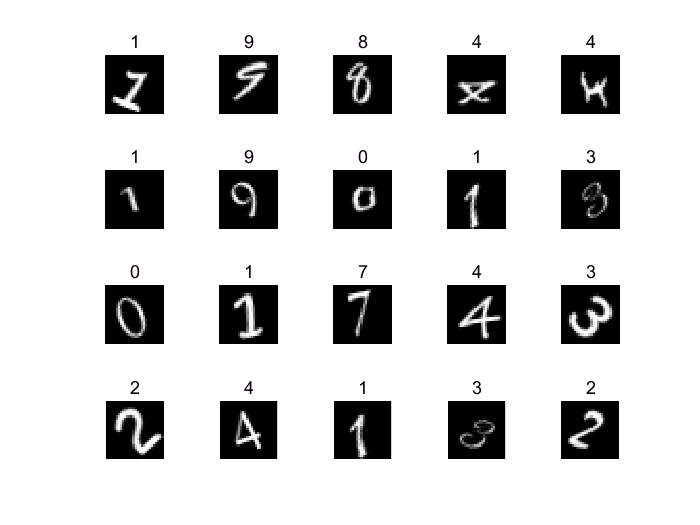

%显示前20个训练照片
numImages = numel(trainDigitData.Files);
idx = randperm(numImages,20);
for i = 1:20
    subplot(4,5,i)

    I = readimage(trainDigitData, idx(i));
    label = char(trainDigitData.Labels(idx(i)));

    imshow(I)
    title(label)
end


% 改变输出层的类别个数
layersTransfer = net.Layers(1:end-3);
% 显示新的类别个数
numClasses =  numel(categories(trainDigitData.Labels));
% 把最后三层替换成新的类别
layers = [...
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];
optionsTransfer = trainingOptions('sgdm',...
    'MaxEpochs',5,...
    'InitialLearnRate',0.0001,...
    'ExecutionEnvironment','cpu');
